# Single dynamic obstalce

=== SCENARIO 1: HEAD-ON AVOIDANCE ===
Goal reached in 288 iterations (28.8 seconds)!
Path length: 24.79 m, Time: 28.8 s, Avg speed: 0.86 m/s

=== SCENARIO 2: OVERTAKING ===
Goal reached in 280 iterations (28.0 seconds)!
Path length: 24.15 m, Time: 28.0 s, Avg speed: 0.86 m/s


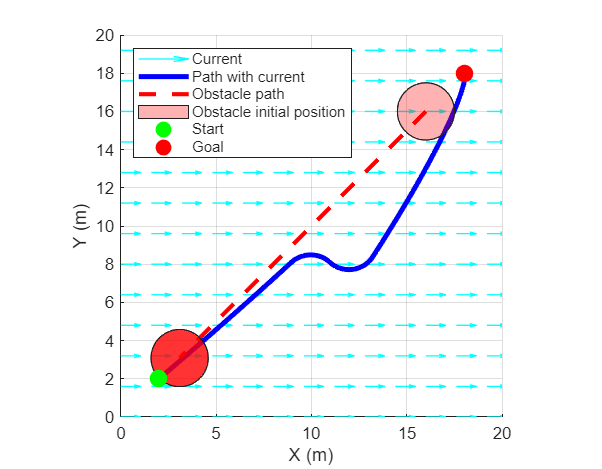

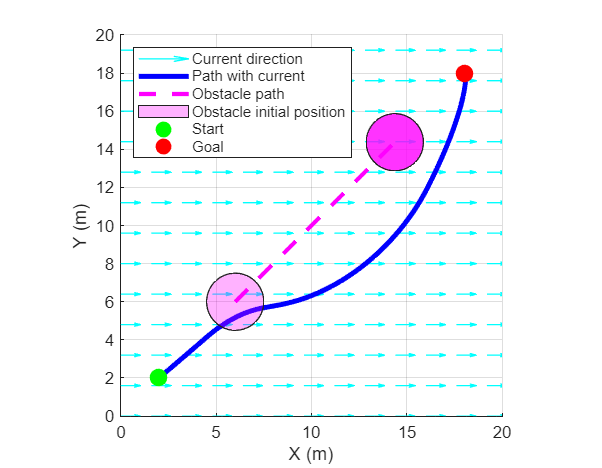

function apf_path_planning_wave_glider_dynamic()
    % APF Path Planning with Wave Glider Dynamics
    % Two scenarios: Head-on avoidance and overtaking

    clear; close all; clc;

    % Environment setup
    field_size = 20;
    resolution = 0.2;
    x = 0:resolution:field_size;
    y = 0:resolution:field_size;
    [X, Y] = meshgrid(x, y);

    % Wave glider parameters
    start_pos = [2, 2];
    goal_pos = [18, 18];
    robot_radius = 0.5;
    
    wave_glider.avg_speed = 0.8;
    wave_glider.turning_radius = 1.2;
    wave_glider.max_turn_rate = wave_glider.avg_speed / wave_glider.turning_radius;

    % APF parameters
    k_att = 1;
    k_rep = 15;
    d0 = 3.5;
    dt = 0.1;
    max_iterations = 3000;

    % Minimal current
    U_current = 0.1;
    [Ux, Uy] = deal(U_current * ones(size(X)), zeros(size(X)));

    %% SCENARIO 1: HEAD-ON AVOIDANCE
    fprintf('=== SCENARIO 1: HEAD-ON AVOIDANCE ===\n');
    obstacles_avoid = [16, 16, 1.5, -0.45, -0.45, 1, 0, 0, 0, 0];
    [path_avoid, history_avoid] = run_scenario(start_pos, goal_pos, obstacles_avoid, ...
        k_att, k_rep, d0, dt, max_iterations, robot_radius, Ux, Uy, wave_glider);

    %% SCENARIO 2: OVERTAKING
    fprintf('\n=== SCENARIO 2: OVERTAKING ===\n');
    obstacles_overtake = [6, 6, 1.5, 0.30, 0.30, 1, 0, 0, 0, 0];
    [path_overtake, history_overtake] = run_scenario(start_pos, goal_pos, obstacles_overtake, ...
        k_att, k_rep, d0, dt, max_iterations, robot_radius, Ux, Uy, wave_glider);

    %% VISUALIZATION
    create_plots(X, Y, start_pos, goal_pos, field_size, Ux, Uy, wave_glider, ...
        obstacles_avoid, path_avoid, history_avoid, ...
        obstacles_overtake, path_overtake, history_overtake);
end

function [path, obstacle_history] = run_scenario(start_pos, goal_pos, dynamic_obstacles, ...
    k_att, k_rep, d0, dt, max_iter, robot_radius, Ux, Uy, wave_glider)

    current_pos = start_pos;
    current_heading = atan2(goal_pos(2) - start_pos(2), goal_pos(1) - start_pos(1));
    current_time = 0;
    
    path = current_pos;
    obstacle_history = {};
    goal_threshold = 0.1;
    c = [Ux(1,1), Uy(1,1)];

    for iter = 1:max_iter
        % Update obstacle position
        current_obstacles = update_obstacle_positions(dynamic_obstacles, current_time);
        obstacle_history{end+1} = current_obstacles; %#ok<AGROW>

        % Calculate forces
        [F_x, F_y] = calculate_forces(current_pos, goal_pos, current_obstacles, ...
            k_att, k_rep, d0, c, wave_glider.avg_speed);

        % Update heading with turning constraints
        desired_heading = atan2(F_y, F_x);
        heading_error = angle_diff(desired_heading, current_heading);
        max_heading_change = wave_glider.max_turn_rate * dt;
        
        if abs(heading_error) > max_heading_change
            current_heading = current_heading + sign(heading_error) * max_heading_change;
        else
            current_heading = desired_heading;
        end
        current_heading = atan2(sin(current_heading), cos(current_heading));

        % Calculate next position
        vx_body = wave_glider.avg_speed * cos(current_heading);
        vy_body = wave_glider.avg_speed * sin(current_heading);
        next_pos = current_pos + dt * ([vx_body, vy_body] + c);
        next_pos = [max(0, min(20, next_pos(1))), max(0, min(20, next_pos(2)))];

        % Collision check
        collision = false;
        for i = 1:size(current_obstacles, 1)
            if norm(next_pos - current_obstacles(i, 1:2)) < (current_obstacles(i, 3) + robot_radius)
                collision = true;
                break;
            end
        end

        if ~collision
            current_pos = next_pos;
            path = [path; current_pos]; %#ok<AGROW>
            current_time = current_time + dt;
        else
            % Emergency avoidance maneuver
            turn_bias = max_heading_change * 1;
            test_heading = current_heading - turn_bias; % Turn right
            test_vx = wave_glider.avg_speed * cos(test_heading) + c(1);
            test_vy = wave_glider.avg_speed * sin(test_heading) + c(2);
            test_pos = current_pos + dt * [test_vx, test_vy];
            
            if all(test_pos >= 0 & test_pos <= 20)
                blocked = false;
                for i = 1:size(current_obstacles, 1)
                    if norm(test_pos - current_obstacles(i, 1:2)) < (current_obstacles(i, 3) + robot_radius)
                        blocked = true;
                        break;
                    end
                end
                if ~blocked
                    current_heading = test_heading;
                    current_pos = test_pos;
                    path = [path; current_pos]; %#ok<AGROW>
                end
            end
            current_time = current_time + dt;
        end

        % Goal check
        if norm(current_pos - goal_pos) < goal_threshold
            fprintf('Goal reached in %d iterations (%.1f seconds)!\n', iter, current_time);
            break;
        end
    end

    if iter == max_iter
        fprintf('Maximum iterations reached. Distance to goal: %.2f m\n', norm(current_pos - goal_pos));
    end

    % Statistics
    if size(path, 1) > 1
        path_length = sum(vecnorm(diff(path), 2, 2));
        fprintf('Path length: %.2f m, Time: %.1f s, Avg speed: %.2f m/s\n', ...
            path_length, current_time, path_length/current_time);
    end
end

function current_obstacles = update_obstacle_positions(dynamic_obstacles, t)
    current_obstacles = zeros(size(dynamic_obstacles, 1), 3);
    for i = 1:size(dynamic_obstacles, 1)
        x0 = dynamic_obstacles(i, 1);
        y0 = dynamic_obstacles(i, 2);
        radius = dynamic_obstacles(i, 3);
        vx = dynamic_obstacles(i, 4);
        vy = dynamic_obstacles(i, 5);
        
        % Linear motion only (motion_type = 1)
        x = x0 + vx * t;
        y = y0 + vy * t;
        current_obstacles(i, :) = [x, y, radius];
    end
end

function [F_x, F_y] = calculate_forces(pos, goal, obstacles, k_att, k_rep, d0, c, v_self)
    x = pos(1); y = pos(2);
    
    % Attractive force
    F_att_x = -k_att * (x - goal(1));
    F_att_y = -k_att * (y - goal(2));

    % Repulsive forces with velocity-aware avoidance
    F_rep_x = 0; F_rep_y = 0;
    F_avoid_x = 0; F_avoid_y = 0;
    
    psi_goal = atan2(goal(2) - y, goal(1) - x);
    e_right = [sin(psi_goal), -cos(psi_goal)]; % Right-hand rule
    
    for i = 1:size(obstacles, 1)
        ox = obstacles(i, 1); oy = obstacles(i, 2); orad = obstacles(i, 3);
        r = [x - ox, y - oy];
        dcen = max(norm(r), eps);
        d_obs = dcen - orad;

        % Standard repulsive force
        if d_obs > 0 && d_obs <= d0
            ux = r(1) / dcen; uy = r(2) / dcen;
            F_rep_mag = k_rep * (1/d_obs - 1/d0) * (1/d_obs^2);
            F_rep_x = F_rep_x + F_rep_mag * ux;
            F_rep_y = F_rep_y + F_rep_mag * uy;
        elseif d_obs <= 0
            ux = r(1) / dcen; uy = r(2) / dcen;
            F_rep_x = F_rep_x + 200 * ux;
            F_rep_y = F_rep_y + 200 * uy;
        end
        
        % Velocity-aware lateral avoidance (starboard bias)
        if dcen < 4 % Close proximity
            lateral_gain = 20 * (4 - dcen) / 4;
            F_avoid_x = F_avoid_x + lateral_gain * e_right(1);
            F_avoid_y = F_avoid_y + lateral_gain * e_right(2);
        end
    end

    % Environmental force (current)
    F_env_x = 0.5 * c(1);
    F_env_y = 0.5 * c(2);

    F_x = F_att_x + F_rep_x + F_env_x + F_avoid_x;
    F_y = F_att_y + F_rep_y + F_env_y + F_avoid_y;
end

function diff = angle_diff(a1, a2)
    diff = a1 - a2;
    diff = atan2(sin(diff), cos(diff));
end

function create_plots(X, Y, start_pos, goal_pos, field_size, Ux, Uy, wave_glider, ...
    obstacles_avoid, path_avoid, history_avoid, obstacles_overtake, path_overtake, history_overtake)

    % Plot 1: Head-on avoidance
    figure('Position', [50, 100, 900, 700]);
    hold on;
    
    % Current field
    skip = 8;
    quiver(X(1:skip:end, 1:skip:end), Y(1:skip:end, 1:skip:end), ...
        Ux(1:skip:end, 1:skip:end)*8, Uy(1:skip:end, 1:skip:end)*8, 0.5, ...
        'Color', [0, 1, 1, 0.4], 'LineWidth', 0.8, 'DisplayName', 'Current');

    % Wave glider path
    plot(path_avoid(:,1), path_avoid(:,2), 'b-', 'LineWidth', 3, 'DisplayName', 'Path with current');

    % Obstacle trajectory
    if ~isempty(history_avoid)
        obstacle_traj = zeros(length(history_avoid), 2);
        for t = 1:length(history_avoid)
            obstacle_traj(t, :) = history_avoid{t}(1, 1:2);
        end
        plot(obstacle_traj(:,1), obstacle_traj(:,2), 'r--', 'LineWidth', 2.5, 'DisplayName', 'Obstacle path');

        % Initial and final obstacle positions
        th = linspace(0, 2*pi, 50);
        initial_obs = history_avoid{1}(1, :);
        final_obs = history_avoid{end}(1, :);
        
        fill(initial_obs(1)+initial_obs(3)*cos(th), initial_obs(2)+initial_obs(3)*sin(th), ...
             'r', 'FaceAlpha', 0.3, 'DisplayName', 'Obstacle initial position');
        fill(final_obs(1)+final_obs(3)*cos(th), final_obs(2)+final_obs(3)*sin(th), ...
             'r', 'FaceAlpha', 0.8, 'HandleVisibility', 'off');
    end

    % Start, goal, direct path
    plot(start_pos(1), start_pos(2), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g', 'DisplayName', 'Start');
    plot(goal_pos(1), goal_pos(2), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r', 'DisplayName', 'Goal');

    xlabel('X (m)'); ylabel('Y (m)');
    legend('Location', 'northwest');
    axis equal; xlim([0, field_size]); ylim([0, field_size]); grid on;

    % Plot 2: Overtaking
    figure('Position', [1000, 100, 900, 700]);
    hold on;
    
    quiver(X(1:skip:end, 1:skip:end), Y(1:skip:end, 1:skip:end), ...
        Ux(1:skip:end, 1:skip:end)*8, Uy(1:skip:end, 1:skip:end)*8, 0.5, ...
        'Color', [0, 1, 1, 0.4], 'LineWidth', 0.8, 'DisplayName', 'Current direction');

    plot(path_overtake(:,1), path_overtake(:,2), 'b-', 'LineWidth', 3, 'DisplayName', 'Path with current');

    if ~isempty(history_overtake)
        obstacle_traj = zeros(length(history_overtake), 2);
        for t = 1:length(history_overtake)
            obstacle_traj(t, :) = history_overtake{t}(1, 1:2);
        end
        plot(obstacle_traj(:,1), obstacle_traj(:,2), 'm--', 'LineWidth', 2.5, 'DisplayName', 'Obstacle path');

        th = linspace(0, 2*pi, 50);
        initial_obs = history_overtake{1}(1, :);
        final_obs = history_overtake{end}(1, :);
        
        fill(initial_obs(1)+initial_obs(3)*cos(th), initial_obs(2)+initial_obs(3)*sin(th), ...
             'm', 'FaceAlpha', 0.3, 'DisplayName', 'Obstacle initial position');
        fill(final_obs(1)+final_obs(3)*cos(th), final_obs(2)+final_obs(3)*sin(th), ...
             'm', 'FaceAlpha', 0.8, 'HandleVisibility', 'off');
    end

    plot(start_pos(1), start_pos(2), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g', 'DisplayName', 'Start');
    plot(goal_pos(1), goal_pos(2), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r', 'DisplayName', 'Goal');

    xlabel('X (m)'); ylabel('Y (m)');
    legend('Location', 'northwest');
    axis equal; xlim([0, field_size]); ylim([0, field_size]); grid on;
end

apf_path_planning_wave_glider_dynamic();